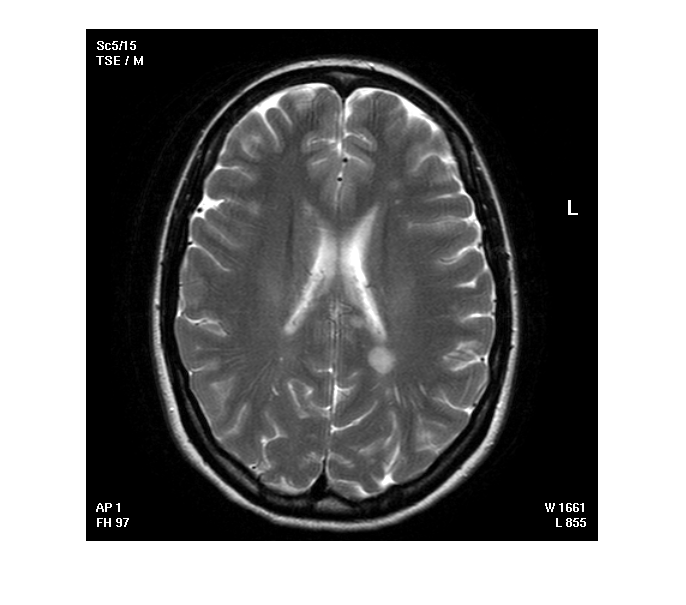

clc, clear all
%load('IM_00240.plq','-mat');
I=imread('IM_00240.tif');
figure, imshow(I)

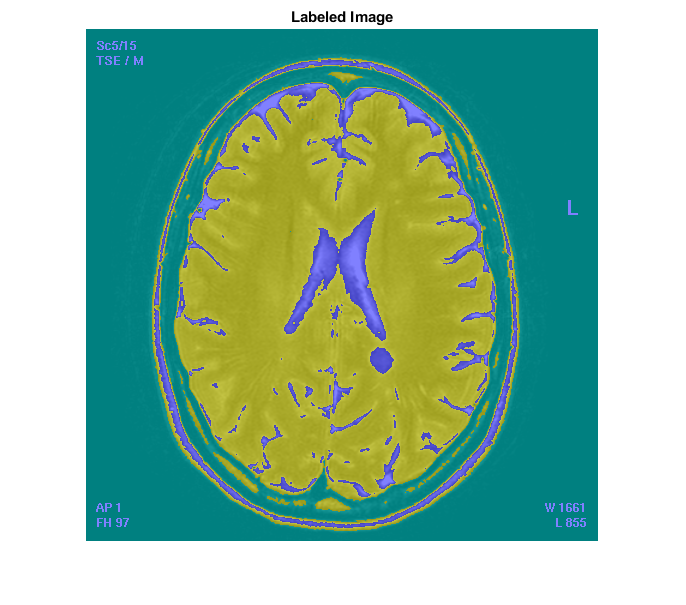

[L,Centers] = imsegkmeans(I,3);
B = labeloverlay(I,L);
imshow(B)
title('Labeled Image')

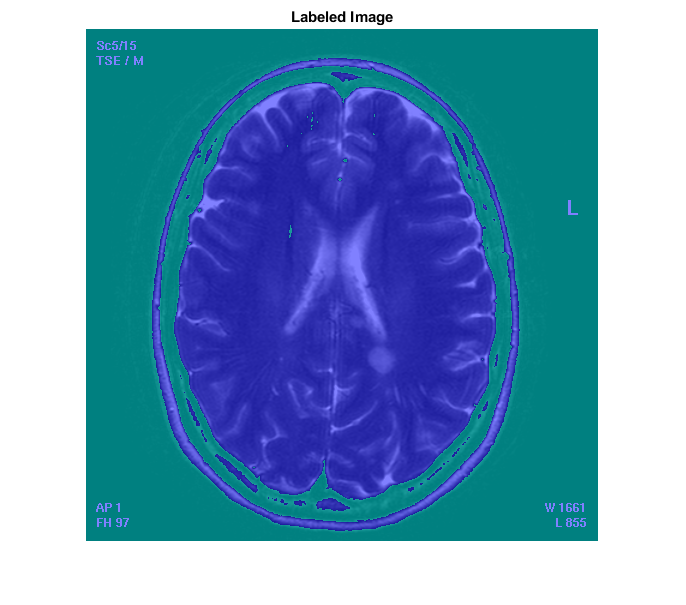


L = imsegkmeans(I,2);
B = labeloverlay(I,L);
imshow(B)
title('Labeled Image')

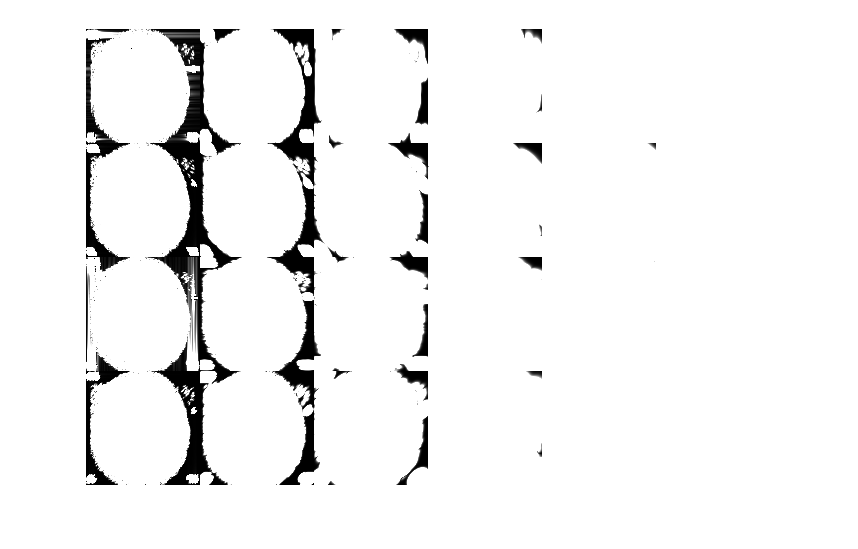


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%Create a set of 24 Gabor filters, covering 6 wavelengths and 4 orientations.
wavelength = 2.^(0:5) * 3;
orientation = 0:45:135;
g = gabor(wavelength,orientation);

%Convert the image to grayscale.
%I = rgb2gray(im2single(I));

%Filter the grayscale image using the Gabor filters. Display the 24 filtered images in a montage.
gabormag = imgaborfilt(I,g);
montage(gabormag,'Size',[4 6])

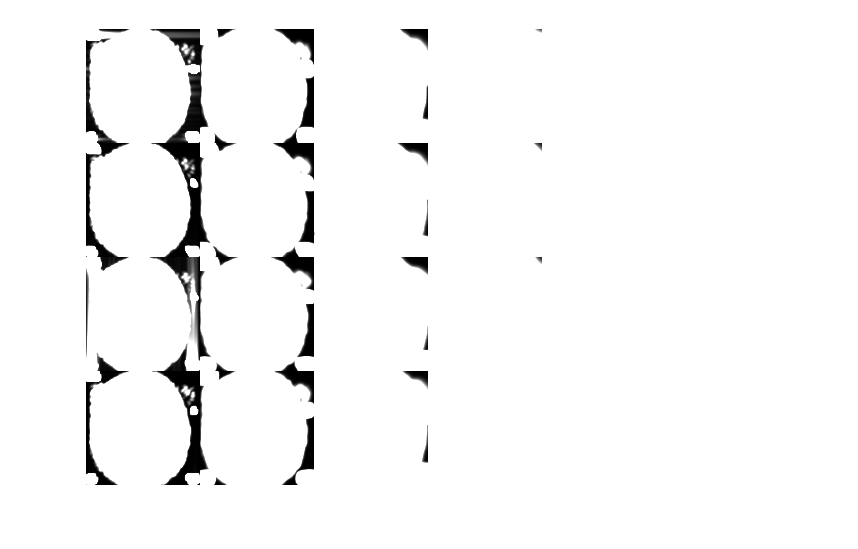


%Smooth each filtered image to remove local variations. Display the smoothed images in a montage.

for i = 1:length(g)
    sigma = 0.5*g(i).Wavelength;
    gabormag(:,:,i) = imgaussfilt(gabormag(:,:,i),3*sigma); 
end
montage(gabormag,'Size',[4 6])

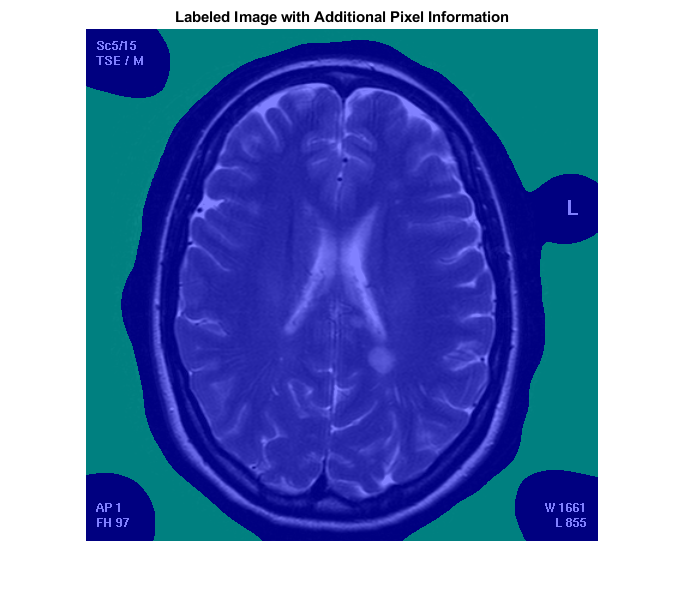


%Get the x and y coordinates of all pixels in the input image.
nrows = size(I,1);
ncols = size(I,2);
[X,Y] = meshgrid(1:ncols,1:nrows);

featureSet = cat(3,I,gabormag,X,Y);

%Segment the image into two regions using k-means clustering with the supplemented feature set.
L2 = imsegkmeans(featureSet,2,'NormalizeInput',true);
C = labeloverlay(I,L2);
imshow(C)
title('Labeled Image with Additional Pixel Information')